# Outline

## How to predict whether bistability will be present?

### 1 Rate-balance plots

### 2 Examples of rate-balance plots in MATLAB

### Rate balance plots

1) Michaelian system with ultrasensitive feedback

[A] <------> [A*]

FR = 

2) Linear feedback plus saturating back reaction

Backward reaction depends on an enzyme reaction

### How can the cell change states?

1) Vary the amount of stimulus [S]

Most plots have assumed [S] =0

But [S] is not 0 usually.

## Rate-balance plots

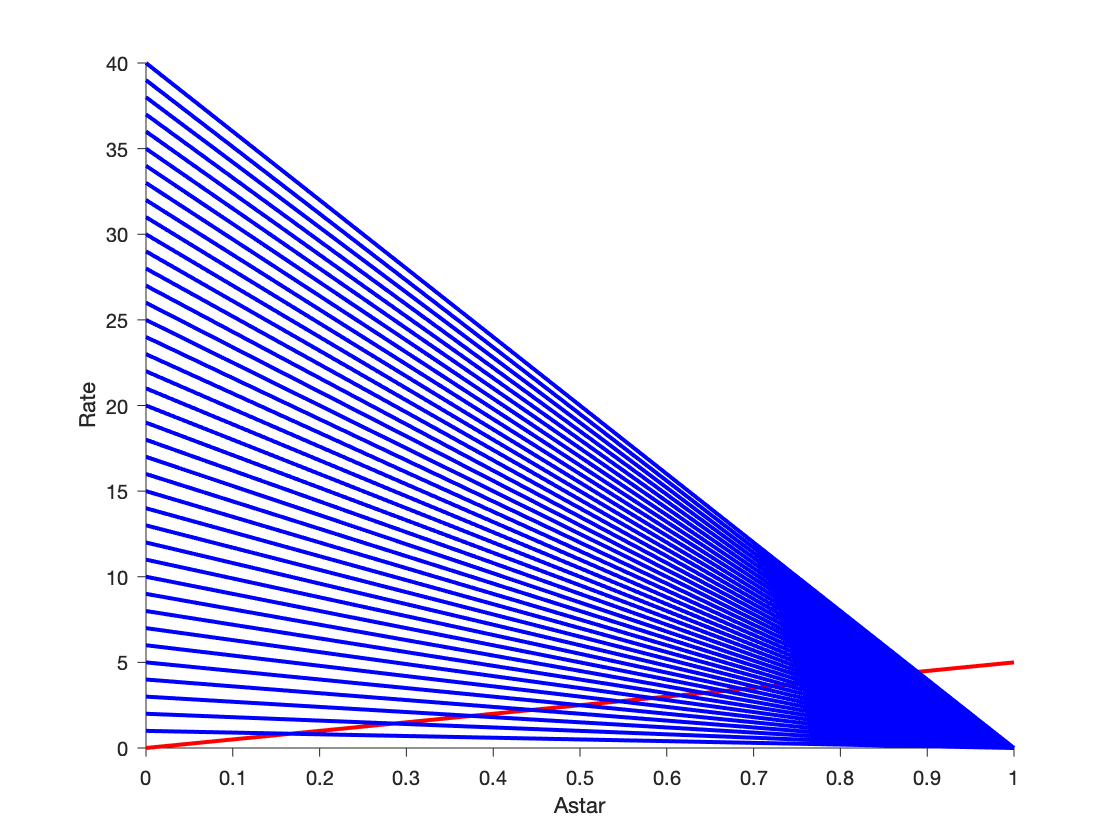

% 1) Linear system with no feedback, forward rate depends on [S]
close all
clear all

Astar = 0:0.01:1;
S = 0.5:0.5:20; % stimulus (40 stimulus, from 0.5 to 20, with step size of 0.5)
kplus = 2; % forward rate constant
kminus = 5; % backward rate constant

BR = kminus*Astar; % backward rate; only has 1 value of BR which will not be changed while change [S], so we here plot it directly.
figure
hold on
plot(Astar, BR, 'r', 'LineWidth',2)
set(gca, 'TickDir','Out') % set the 'get current axis, Tick directory is out.
% y axis is backward rate; x axis is A star.

% for the forward rate, it related to [S], we here want to generate FR
% based on different [S], so here we need for loop.
for i = 1:length(S) % for different [S]
    FR = kplus*S(i)*(1-Astar); % [A] = 1-[Astar]
    [mindummy,dex]=min(abs(FR-BR)); %where is the steady state; use dummy minimum since we don't care what exactly the value is.
    A_SS(i) = Astar(dex);
    plot(Astar,FR,'b','LineWidth',2) % plot out Astar Vs. forward rate
end

axis([0 1 0 max(FR)]) %define the axis, x axis and y axis.
xlabel('Astar')
ylabel('Rate')

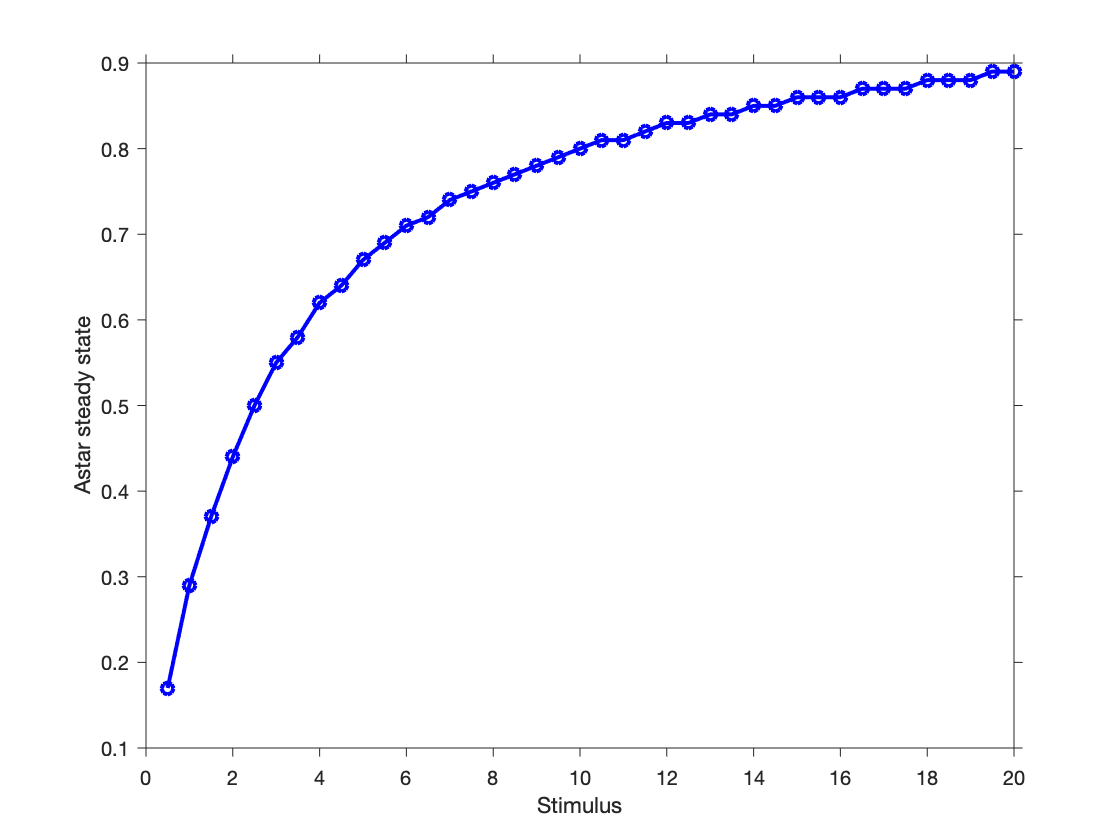


figure
plot(S,A_SS,'bo-','LineWidth',2)% summary plot in the end, many [S] (x axis) and many steady state of Astar (y axis).
set(gca,'TickDir','Out')% b is blue, o is open circle, - is connected with '-'
xlabel('Stimulus')
ylabel('Astar steady state')

% These are rate balance plots.


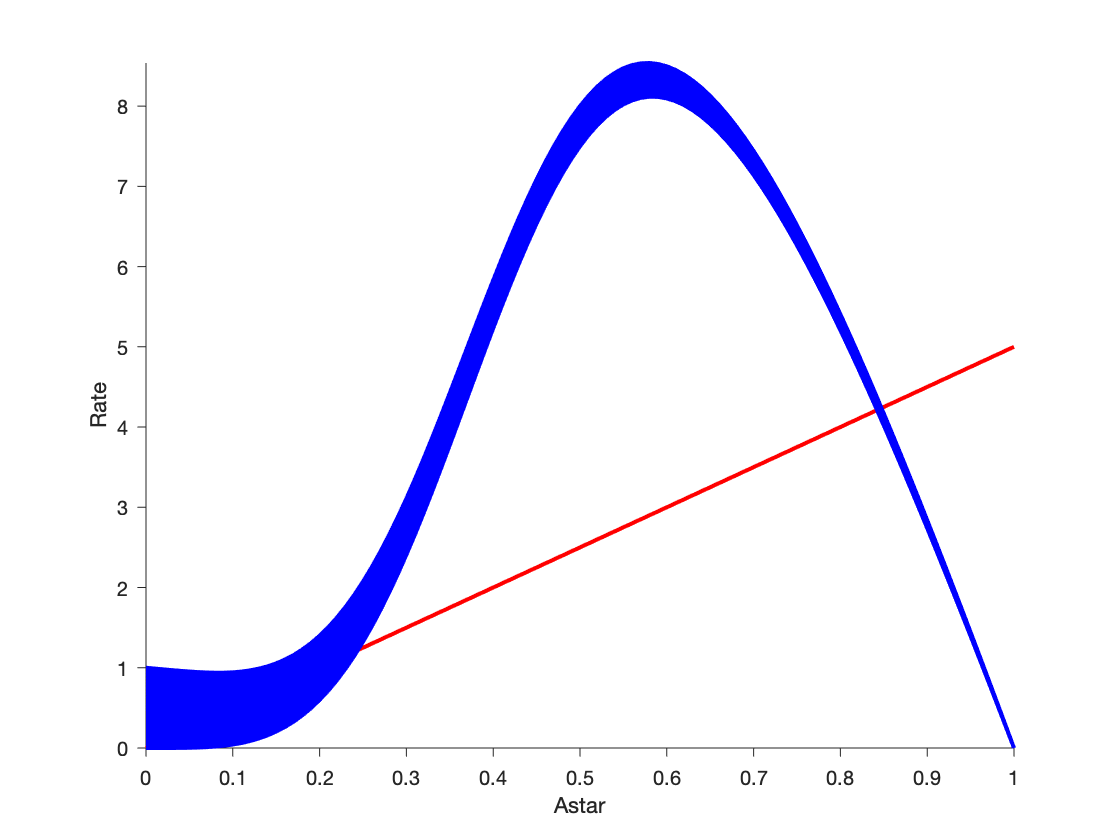


% 2) Ultrasensitive feedback, varaible [S]
close all
clear all

Astar = 0:0.01:1;
S = 0:0.02:0.5;
kplus = 2;
kfs = 30; % 
Kmf = 0.5;
kminus = 5;
h = 4; % exponent

BR = kminus*Astar ;
figure
handle1 = gcf;% tell MATLAB the figure handle, get current figure (gcf), if you are at figure 1 and you call gcf, you'll get the answer as 1.
hold on 
plot(Astar, BR, 'r','LineWidth',2) %this is the rate-balance plot
set(gca, 'TickDir','Out')

figure 
handle2 = gcf; % This will be the summary plot-handle2, allows us to flip back and forth.
hold on


for i=1:length(S)
    FR = (kplus*S(i) + kfs*(Astar.^h./(Astar.^h+Kmf^h))).*(1-Astar); %define ultrasensitive relationship.Note .^(./)h(element by element power), h is the power as 4. 
    figure(handle1)% tell MATLAB what is the figure, it is the handle1.
    plot(Astar, FR, 'b','LineWidth',2)% plot rate-balance on figure handle1.
    
    crossings = []; % as we did not know whether FR-BR will intersect at all or how many times. So define an empty variable to hold these possibilities.
    difference = FR-BR;% anytime we go through from positive to negative or 0, there is a intersect.
    for iii = 2:length(FR)
        if (sign(difference(iii)) ~= sign(difference(iii-1)))%test whether the sign are same.
            crossings = [crossings, iii];% 1 or 3 steadystates points (index) of Astar.
        end
    end
    figure(handle2) % plot summary plot onto handle2
    plot(S(i),Astar(crossings),'bo') %crossing is which element you are at (iii).
end

figure(handle1)
axis([0 1 0 max(FR)])
set(gca, 'TickDir','Out')
xlabel('Astar')
ylabel('Rate')

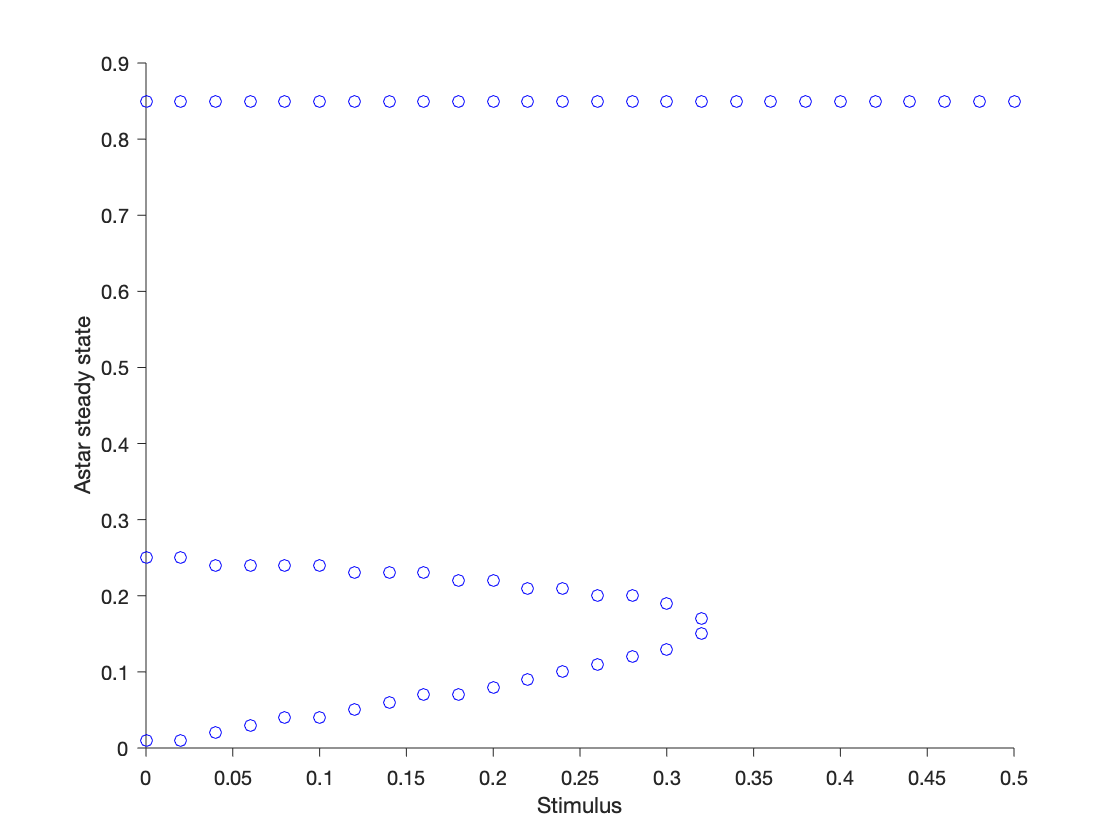


figure(handle2)
set(gca, 'TickDir','Out')

xlabel('Stimulus')
ylabel('Astar steady state')

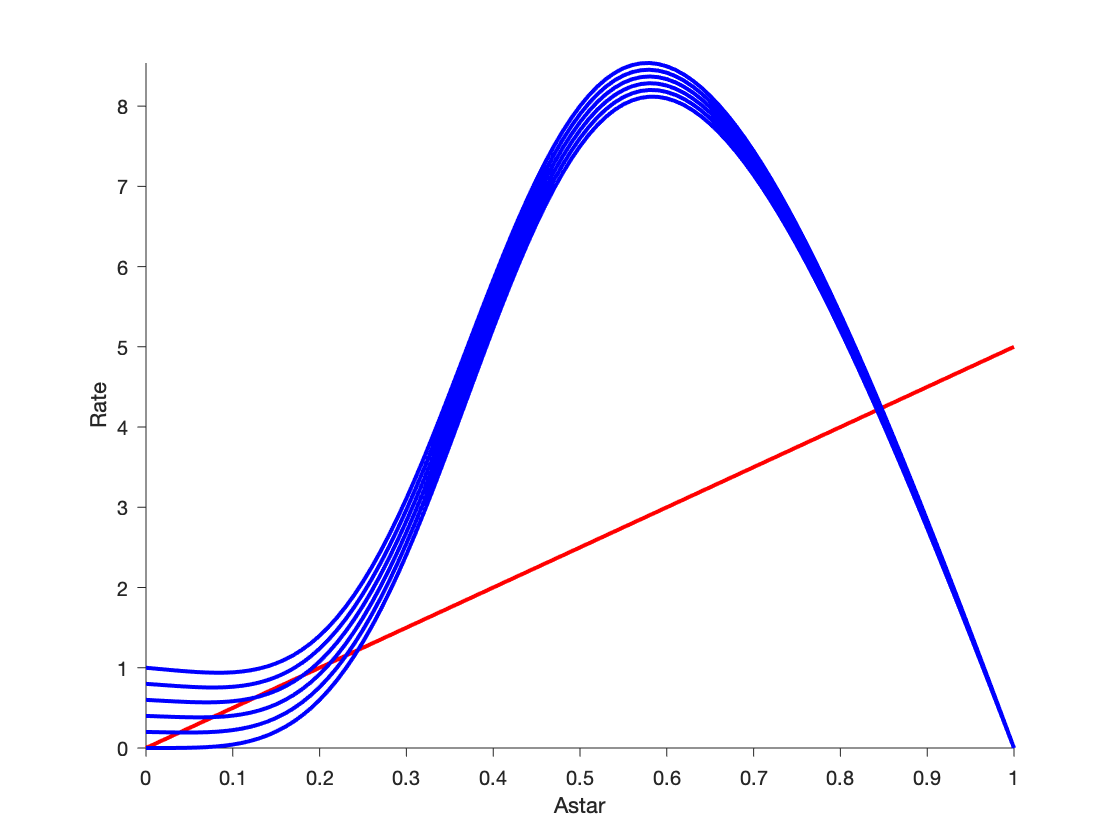


% low [S], two curves cross 3 times, as [S] get larger, there is only 1
% cross.

% can plot fewer [S] values to see the figure 1 more clearly.

close all
clear all

Astar = 0:0.01:1;
S = 0:0.1:0.5; % here plot fewer [S] with step size of 0.1, only 5 values of [S] to have clearer plot.
kplus = 2;
kfs = 30; % 
Kmf = 0.5;
kminus = 5;
h = 4; % exponent

BR = kminus*Astar ;
figure
handle1 = gcf;% tell MATLAB the figure handle, get current figure (gcf), if you are at figure 1 and you call gcf, you'll get the answer as 1.
hold on 
plot(Astar, BR, 'r','LineWidth',2) %this is the rate-balance plot
set(gca, 'TickDir','Out')

figure 
handle2 = gcf; % This will be the summary plot-handle2, allows us to flip back and forth.
hold on


for i=1:length(S)
    FR = (kplus*S(i) + kfs*(Astar.^h./(Astar.^h+Kmf^h))).*(1-Astar); %define ultrasensitive relationship.Note .^(./)h(element by element power), h is the power as 4. 
    figure(handle1)% tell MATLAB what is the figure, it is the handle1.
    plot(Astar, FR, 'b','LineWidth',2)% plot rate-balance on figure handle1.
    
    crossings = []; % as we did not know whether FR-BR will intersect at all or how many times. So define an empty variable to hold these possibilities.
    difference = FR-BR;% anytime we go through from positive to negative or 0, there is a intersect.
    for iii = 2:length(FR)
        if (sign(difference(iii)) ~= sign(difference(iii-1)))%test whether the sign are same.
            crossings = [crossings, iii];% 1 or 3 steadystates points (index) of Astar.
        end
    end
    figure(handle2) % plot summary plot onto handle2
    plot(S(i),Astar(crossings),'bo') %crossing is which element you are at (iii).
end

figure(handle1)
axis([0 1 0 max(FR)])
set(gca, 'TickDir','Out')
xlabel('Astar')
ylabel('Rate')

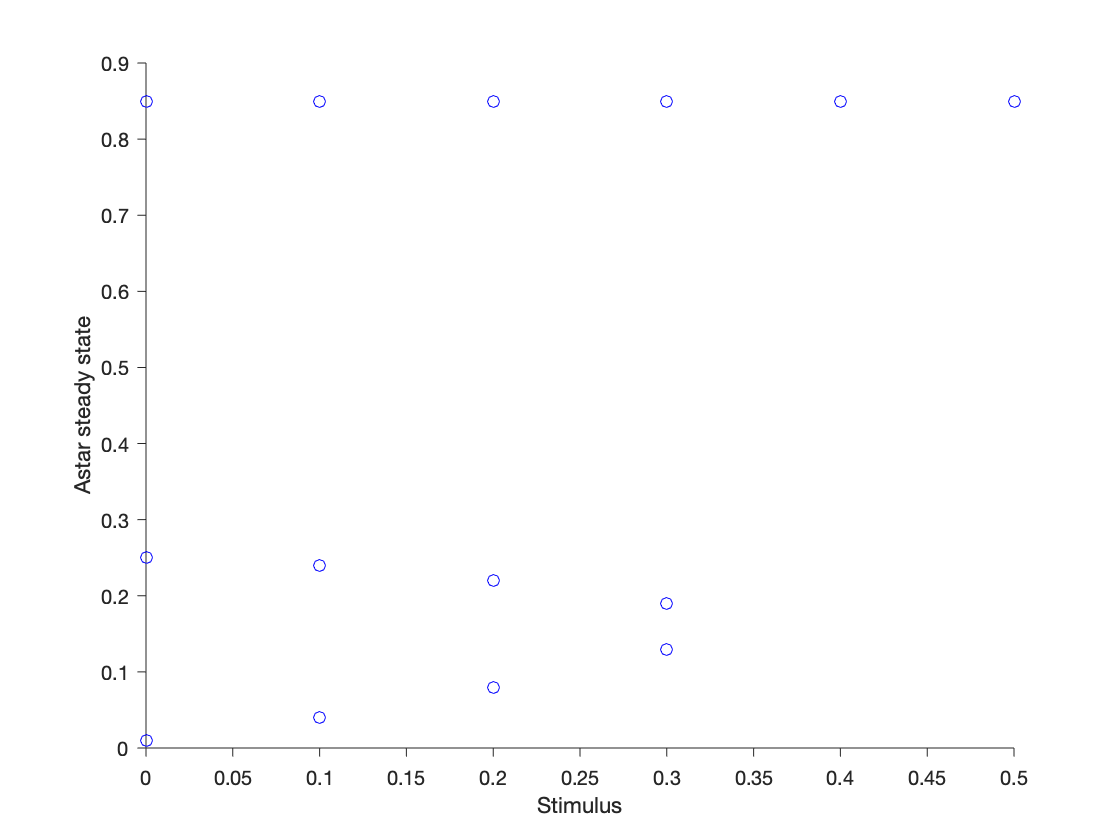


figure(handle2)
set(gca, 'TickDir','Out')

xlabel('Stimulus')
ylabel('Astar steady state')